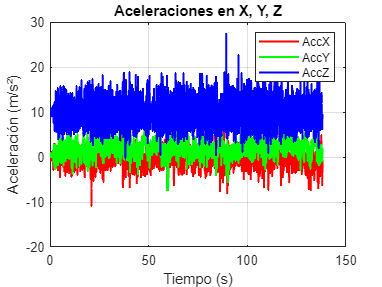

% Leer archivo JSON
jsonText = fileread('IMU.json');

% Decodificar
jsonData = jsondecode(jsonText);

% Extraer valores
values = jsonData.payload.values;

% Extraer columnas de datos
accX = values(:,1);
accY = values(:,2);
accZ = values(:,3);

% Calcular tiempo total
interval_ms = jsonData.payload.interval_ms;
time = (0:length(values)-1) * interval_ms/1000;

% Graficar aceleraciones obtenidas
plot(time, accX, 'r-', time, accY, 'g-', time, accZ, 'b-', 'LineWidth', 1.5);
title('Aceleraciones en X, Y, Z');
xlabel('Tiempo (s)');
ylabel('Aceleración (m/s²)');
legend('AccX', 'AccY', 'AccZ');
grid on;

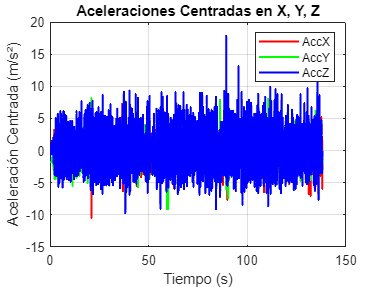


% Calcular y restar media para cada aceleración
accX_centered = accX - mean(accX);
accY_centered = accY - mean(accY);
accZ_centered = accZ - mean(accZ);

% Graficar aceleraciones centradas
plot(time, accX_centered, 'r-', time, accY_centered, 'g-', time, accZ_centered, 'b-', 'LineWidth', 1.5);
title('Aceleraciones Centradas en X, Y, Z');
xlabel('Tiempo (s)');
ylabel('Aceleración Centrada (m/s²)');
legend('AccX', 'AccY', 'AccZ');
grid on;

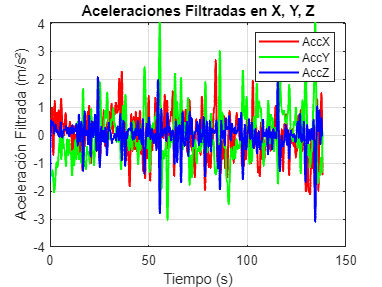


% Frecuencia de muestreo
fs = 1000 / interval_ms;

% Filtro Pasabajos FIR
cutoff_freq = fs/60;  % Frecuencia debe ser menor a fs/2
filter_order = 200;   % Ajustar para mejor banda de rechazo

% Filtro FIR por ventana de Hamming
fir_filter = fir1(filter_order, cutoff_freq/(fs/2), 'low');

% Aplicar filtro a las aceleraciones
accX_filtered = filtfilt(fir_filter, 1, accX_centered);
accY_filtered = filtfilt(fir_filter, 1, accY_centered);
accZ_filtered = filtfilt(fir_filter, 1, accZ_centered);

% Graficar aceleraciones filtradas
plot(time, accX_filtered, 'r-', time, accY_filtered, 'g-', time, accZ_filtered, 'b-', 'LineWidth', 1.5);
title('Aceleraciones Filtradas en X, Y, Z');
xlabel('Tiempo (s)');
ylabel('Aceleración Filtrada (m/s²)');
legend('AccX', 'AccY', 'AccZ');
grid on;

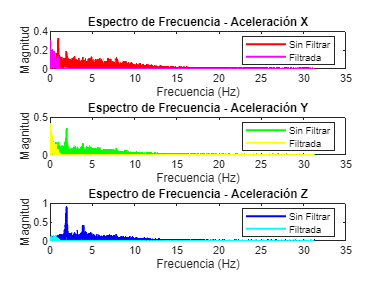


% FFT para X, Y, Z (filtradas y sin filtrar)
N = length(time);
half_N = floor(N/2) + 1;
f = (0:half_N-1) * (fs/N);  % Eje de frecuencia

% Filtrada y sin filtrar para cada eje
axes = {'X', 'Y', 'Z'};
centered_data = {accX_centered, accY_centered, accZ_centered};
filtered_data = {accX_filtered, accY_filtered, accZ_filtered};
colors_raw = {'r', 'g', 'b'};
colors_filtered = {'m', 'y', 'c'};

figure;
for i = 1:3
   % Sin filtrar
   fft_raw = fft(centered_data{i});
   P1_raw = abs(fft_raw/N);
   P1_raw = P1_raw(1:half_N);
   P1_raw(2:end-1) = 2*P1_raw(2:end-1);
   
   % Filtrada
   fft_filtered = fft(filtered_data{i});
   P1_filtered = abs(fft_filtered/N);
   P1_filtered = P1_filtered(1:half_N);
   P1_filtered(2:end-1) = 2*P1_filtered(2:end-1);
   
   subplot(3,1,i);
   plot(f, P1_raw, colors_raw{i}, f, P1_filtered, colors_filtered{i}, 'LineWidth', 1.5);
   title(['Espectro de Frecuencia - Aceleración ' axes{i}]);
   xlabel('Frecuencia (Hz)');
   ylabel('Magnitud');
   legend('Sin Filtrar', 'Filtrada');
end

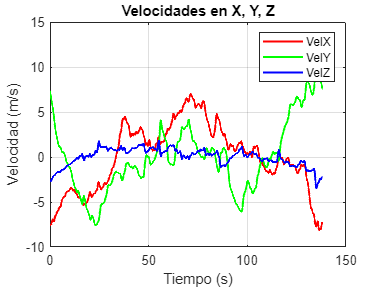


% Cálculo velocidad
velX = cumtrapz(time, accX_filtered);
velY = cumtrapz(time, accY_filtered);
velZ = cumtrapz(time, accZ_filtered);

% Restar media para centrar velocidades
velX_centered = velX - mean(velX);
velY_centered = velY - mean(velY);
velZ_centered = velZ - mean(velZ);

% Graficar velocidades
figure()
plot(time, velX_centered, 'r-', time, velY_centered, 'g-', time, velZ_centered, 'b-', 'LineWidth', 1.5);
title('Velocidades en X, Y, Z');
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
legend('VelX', 'VelY', 'VelZ');
grid on;

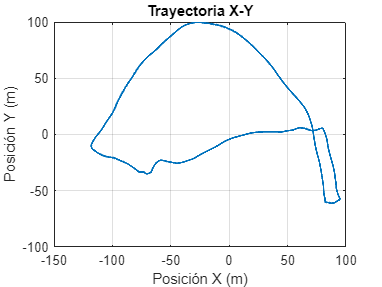


% Cálculo de posición
posX = cumtrapz(time, velX_centered);
posY = cumtrapz(time, velY_centered);
posZ = cumtrapz(time, velZ_centered);

% Restar media para centrar posición
posX_centered = posX - mean(posX);
posY_centered = posY - mean(posY);
posZ_centered = posZ - mean(posZ);

% Gráfica de trayecto en R2
figure();
plot(posX_centered, posY_centered, 'LineWidth', 1.5);
title('Trayectoria X-Y');
xlabel('Posición X (m)');
ylabel('Posición Y (m)');
grid on;